num = 2;
objective_func = @Rastrigin;

hjhj


Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossovertwopoint
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationpositivebasis

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1             1000          0.5837           28.33        0
    2             1475          0.5687           20.84        0
    3             1950          0.1725            15.2        0
    4             2425        0.001554           12.97        0
    5             2900        0.001554           10.86        1
    6             3375        0.001554           11.13        2
    7             3850        0.001554           10.75        3
    8             4325        0.001554           11.02        4
    9             4800        0.001554           10.33        5
   10             5275        0.001554           9.211        6
   11       

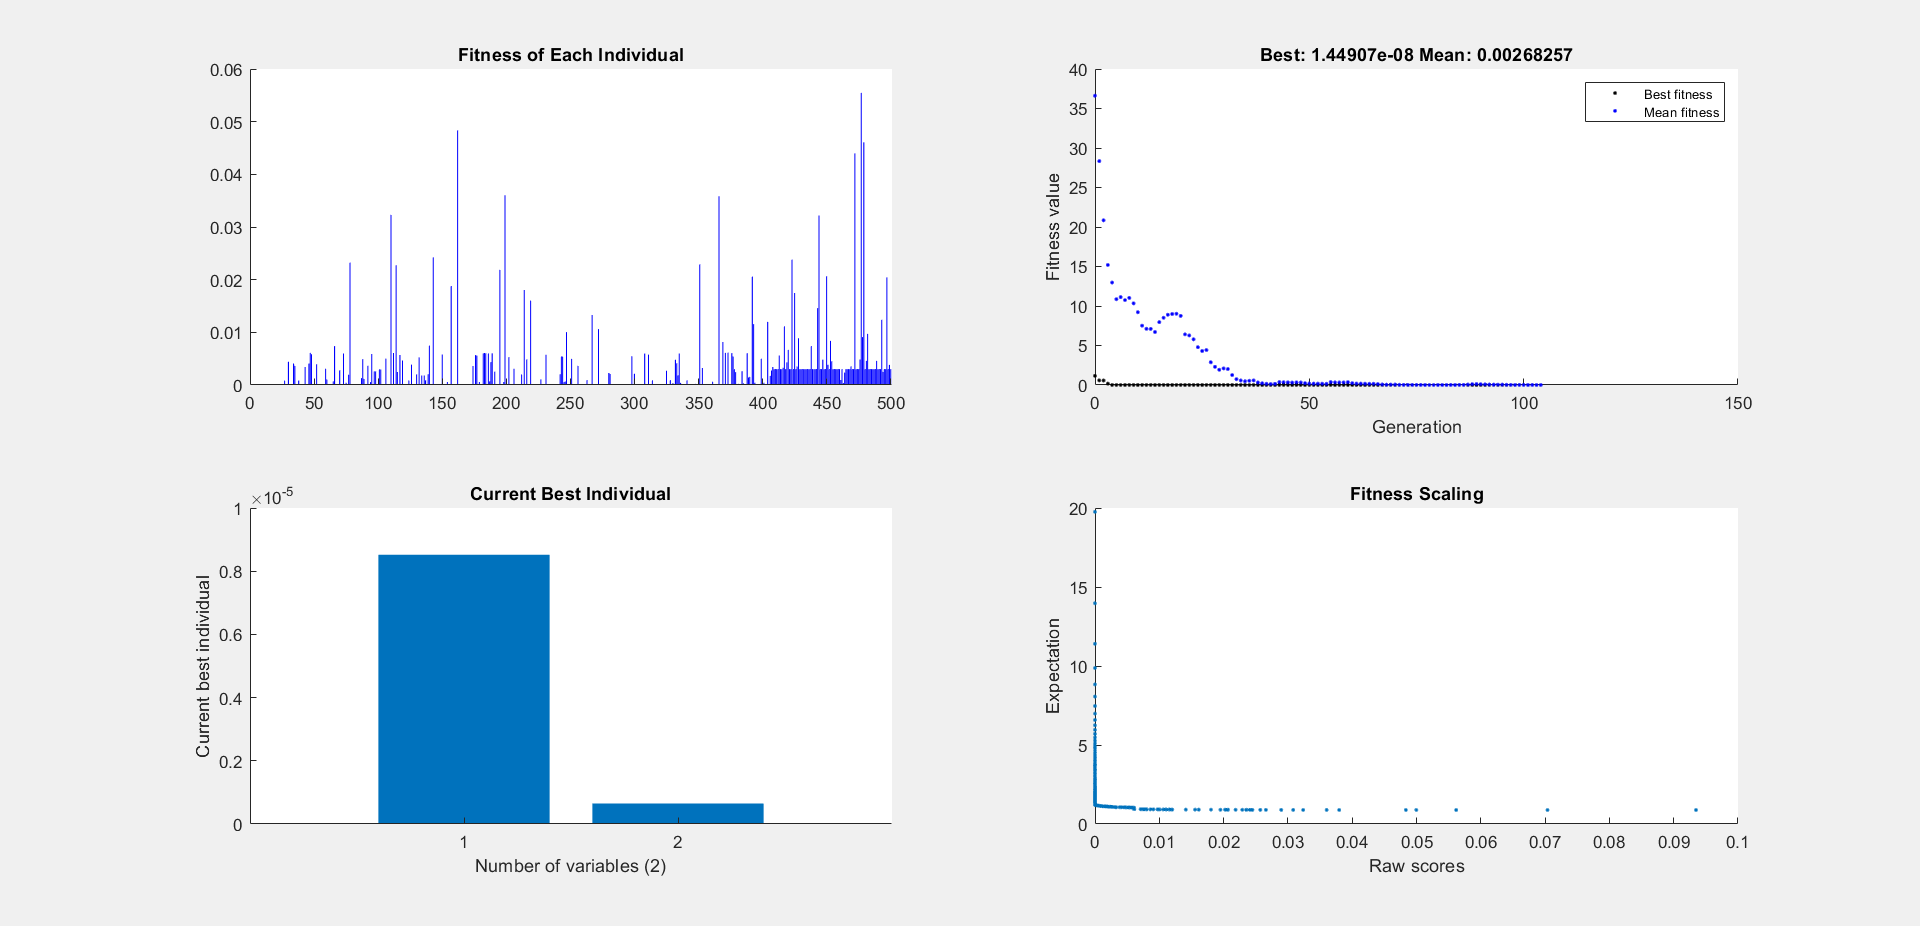

% Set nondefault solver options
options = optimoptions("ga","MutationFcn","mutationadaptfeasible",...
    "CrossoverFcn","crossoverheuristic","PopulationSize",500,...
    "MaxGenerations",150,"Display","iter","PlotFcn",["gaplotscores",...
    "gaplotbestf","gaplotbestindiv","gaplotexpectation"]);

% Solve
[solution,objectiveValue] = ga(@Rastrigin,num,[],[],[],[],repmat(-5.12,num,...
    1),repmat(5.12,num,1),[],[],options);


% Clear variables
clearvars options



disp(objectiveValue);

   1.4491e-08



disp(solution);

   1.0e-05 *

    0.8522    0.0648

